# create timetable from gdt file

## loading the file and extracting the table

clear
%gdt
options = detectImportOptions('ANON_19810211.GDT', 'FileType','text');
T = readtable('ANON_19810211.GDT', options); 

%edf

edfFile1 = edfread('ANONCapno edf export -1.edf');
edfFile2 = edfread('HT capno.edf');
edfFile3 = edfread('GD capno.edf');
edfFile4 = edfread('WP capno.edf');

edfFile = edfFile1(1:find(edfFile1.PR,1,'last'),:); %remove zeros from end of file

display('loading file: done');

loading file: done


## removing NaN values

%gdt
T.PaCO2(isnan(T.PaCO2)) = 0; %replace Nan values with 0 so they dont get removed in next step
gdtfile = T(~any(ismissing(T),2),:);%remove all rows that have missing value or NaN. now we only have the table remaining.
display('removing NaN: done');

removing NaN: done


## samplingTime and samplePeriod

%gdt

gdtTimes = duration(gdtfile.Time, 'InputFormat','mm:ss');%convert to duration
gdtTimes=seconds(gdtTimes)

gdtTimes =     10
    20
    30
    40
    50
    60
    70
    80
    90
   100


%gdtSamplePeriod = round(mean(diff(gdtTimes)));%average time difference between samples
gdtSamplePeriod = median(diff(gdtTimes))%average time difference between samples

gdtSamplePeriod = 10

gdtSampleRate = 1/gdtSamplePeriod

gdtSampleRate = 0.1000


% edf
edfTimes = seconds(duration(edfFile.("Record Time")));
%edfSamplePeriod = round(mean(diff(edfDuration)));
edfSamplePeriod = median(diff(edfTimes));
edfSampleRate = 1/edfSamplePeriod;
display('initializing vars: done');

initializing vars: done


## convert gdt table to timetable

minutes = str2double(extractBefore(gdtfile.Time, ':'));%extract time from column  
seconds = str2double(extractAfter(gdtfile.Time, ':'));
timeDuration = duration(0, minutes, seconds);
clear seconds;
clear minutes;
gdtfile.Time=[];%remove time column
gdtTimeTable=(table2timetable(gdtfile,'RowTimes',timeDuration));
gdtTimeTable.Properties.VariableContinuity= {'continuous','continuous','continuous','continuous','continuous','continuous','continuous','continuous','continuous','continuous','continuous'};
gdtfile=retime(gdtTimeTable,'regular','SampleRate',gdtSampleRate);
gdtTimes = seconds(duration(gdtfile.Time));

display('converting to timetables: done');

converting to timetables: done


## Fourier transform and plots

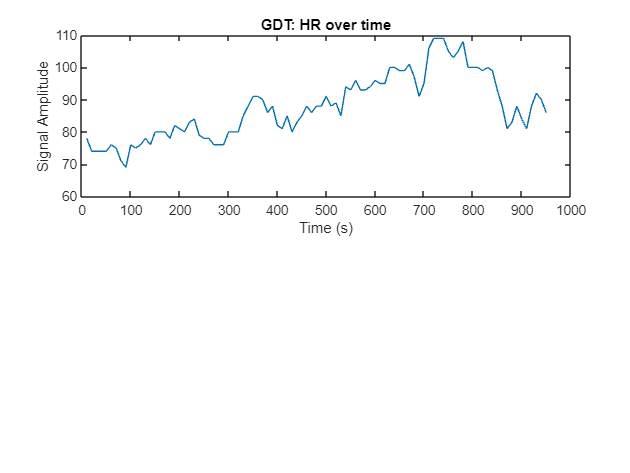

%gdt
signalGdt = gdtfile.HR; %the signal you want to convert
nGdt = length(signalGdt);%signalLength
freqRangeGdt = (0:nGdt-1)*(gdtSamplePeriod/nGdt); % frequency range
fftGdt = fft(signalGdt)/nGdt; % Fourier transform
powerGdt = abs(fftGdt); % power spectrum
figure
subplot(2,1,1)
plot(gdtTimes, signalGdt)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('GDT: HR over time')

% 
% subplot(2,1,2)
% plot(freqRangeGdt,powerGdt)
% xlabel('Frequency (Hz)')
% ylabel('Power')
% title('Frequency Domain')


## edf

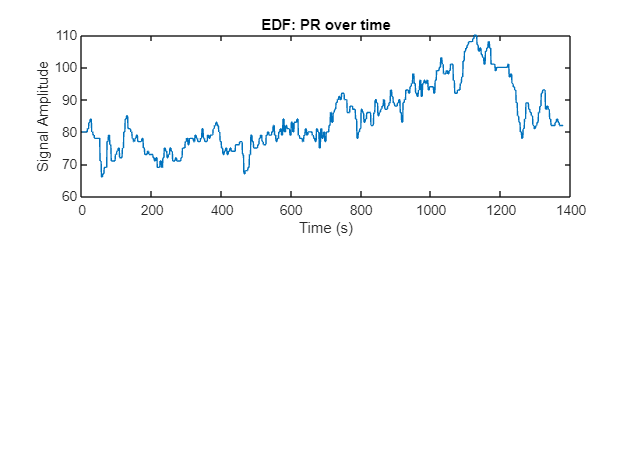

signalEdf = edfFile.PR; %the signal you want to convert
nEdf = length(signalEdf);
freqRangeEdf = (0:nEdf-1)*(edfSamplePeriod/nEdf); % frequency range
fftEdf = fft(signalEdf)/nEdf; % Fourier transform
powerEdf = abs(fftEdf); % power spectrum

figure
subplot(2,1,1)
plot(edfTimes, signalEdf)
xlabel('Time (s)')
ylabel('Signal Amplitude')
title('EDF: PR over time')


% subplot(2,1,2)
% plot(freqRangeEdf,powerEdf)
% xlabel('Frequency (Hz)')
% ylabel('Power')
% title('Frequency Domain')

display('Fourier transforms: done');

Fourier transforms: done


## upsample gdt

upFactor=edfSampleRate/gdtSampleRate;
upGdt = interp(signalGdt, upFactor);
length(upGdt)

ans = 950

length(signalGdt)

ans = 95

upGDTDuration = interp(gdtTimes, upFactor);
dt = mean(diff(upGDTDuration)); 
% up_Fs  = 1 / dt; %sampling frequency gdt
% up_period = 1/up_Fs; %sampling period
% n = length(upGdt);
% f = (0:n-1)*(up_Fs/n); % frequency range
% Y = fft(upGdt)/n; % Fourier transform
% powerUpGdt = abs(Y); % power spectrum
display('upsampling gdt: done');

upsampling gdt: done


## cross correlation

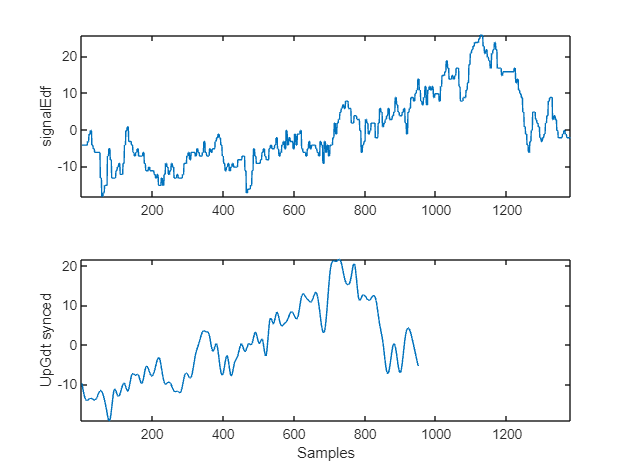

s1=signalEdf;
s1=s1-mean(s1);
%remove dc offset
s2=upGdt;
s2=s2-mean(s2);

ax(1) = subplot(2,1,1);
plot(s1)
ylabel('signalEdf')
axis tight

ax(2) = subplot(2,1,2);
plot(s2)
ylabel('UpGdt synced')
axis tight

xlabel('Samples')

linkaxes(ax,'x')

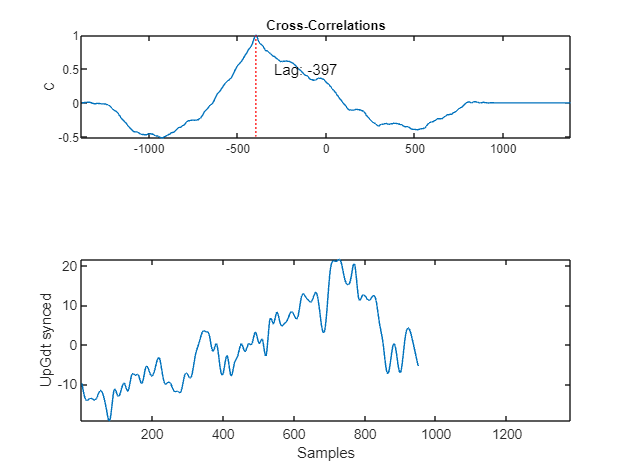


[C,lags] = xcorr(s2,s1);
C = C/max(C);%normalize

[M,I] = max(C);
t = lags(I);

subplot(3,1,1)
plot(lags,C,[t t],[-0.5 1],'r:')
text(t+100,0.5,['Lag: ' int2str(t)])
ylabel('C')
axis tight
title('Cross-Correlations')

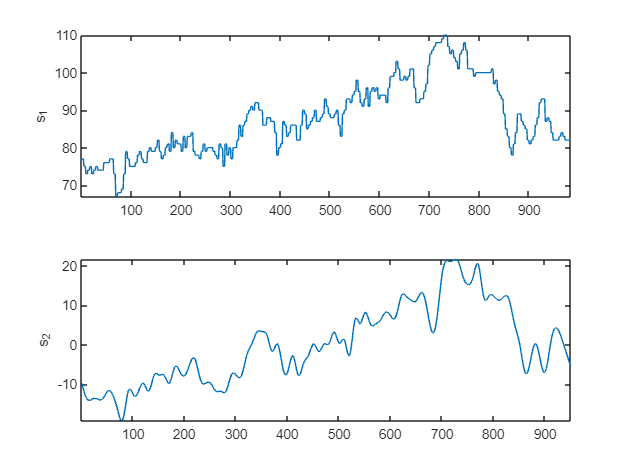


edf_cor = signalEdf(-t:end);
s1_synced= s1(-t:end);

ax(1) = subplot(2,1,1);
plot(edf_cor)
ylabel('s_1')
axis tight

ax(2) = subplot(2,1,2);
plot(s2)
ylabel('s_2')
axis tight

## plot together

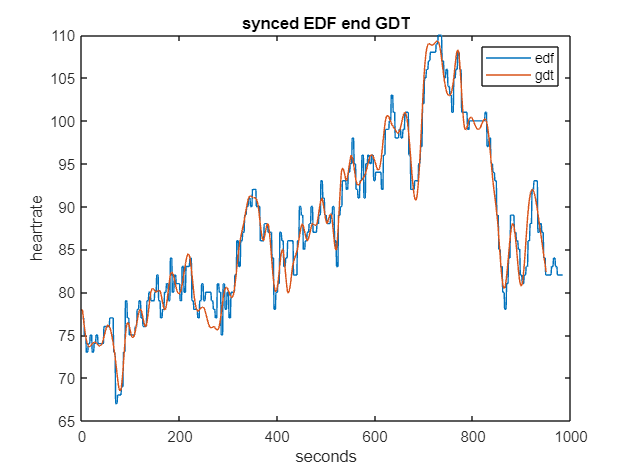

figure
plot(edf_cor)
hold on
plot (upGdt)
ylabel('heartrate')
xlabel('seconds')
title('synced EDF end GDT')
legend('edf','gdt')
hold off

## calculate maximum and minimum

maxValueEdf=max(edf_cor)

maxValueEdf = 110

maxTimeEdf = median(find(edf_cor == maxValueEdf))

maxTimeEdf = 732.5000

minValueEdf=min(edf_cor)

minValueEdf = 67

minTimeEdf = median(find(edf_cor == minValueEdf))

minTimeEdf = 70.5000


maxValueGdt=max(upGdt)

maxValueGdt = 109.3240

maxTimeGdt = median(find(upGdt == maxValueGdt))

maxTimeGdt = 727

minValueGdt=min(upGdt)

minValueGdt = 68.4920

minTimeGdt = median(find(upGdt == minValueGdt))

minTimeGdt = 78


maxValueDiff=maxValueGdt-maxValueEdf

maxValueDiff = -0.6760

maxTimeDiff=maxTimeGdt-maxTimeEdf

maxTimeDiff = -5.5000

minValueDiff=minValueGdt-minValueEdf

minValueDiff = 1.4920

minTimeDiff=minTimeGdt-minTimeEdf

minTimeDiff = 7.5000

## calulate engery consumed

%mean(load)*duration
%calc calories from joules


## write to csv

maxLen = max([numel(edf_cor), numel(upGdt)]);
[fileName,path] = uiputfile('*.xlsx')

fileName = 'test.xlsx'

path = 'D:\Data\DSP\6_DSP_Practicum\'


% Convert vectors to cell arrays with NaN padding
cellVector1 = num2cell([edf_cor; NaN(maxLen - numel(edf_cor), 1)]);
cellVector2 = num2cell([upGdt; NaN(maxLen - numel(upGdt), 1)]);
signalNames = { 'Edf synced','Gdt upsampled+synced'};
signalTable = table(cellVector1, cellVector2, 'VariableNames', signalNames);
writetable(signalTable, strcat(path,fileName), 'Sheet', 1);
